# 从文本文件中导入数据

用于从以下文本文件中导入数据的脚本:

clear variables

filedir="\\ARTEMIS-PC\Data\2026-04-13\ROT2.txt";

由 MATLAB 于 2022-07-07 16:13:50 自动生成

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 11);

% 指定范围和分隔符
opts.DataLines = [4, Inf];
opts.Delimiter = ["\t", ","];

% 指定列名称和类型
opts.VariableNames = ["Var1", "S1", "S2", "S3", "eta", "phi", "Var7","Var8","Var9","Var10","Var11"];
opts.SelectedVariableNames = ["S1", "S2", "S3", "eta", "phi"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "string", "string", "string", "string"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% 指定变量属性
opts = setvaropts(opts, ["Var1", "Var7", "Var8", "Var9", "Var10", "Var11"]);
opts = setvaropts(opts, ["Var1", "Var7", "Var8", "Var9", "Var10", "Var11"], "EmptyFieldRule", "auto");

% 导入数据
tbl = readtable(filedir, opts);

## 转换为输出类型

S1 = tbl.S1;
S2 = tbl.S2;
S3 = tbl.S3;
eta = tbl.eta;
phi = tbl.phi;

## 清除临时变量

clear opts tbl

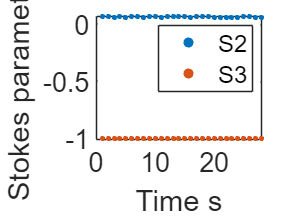

close all
scatter(1:length(S2),S2,10,'filled')
hold on
scatter(1:length(S2),S3,10,'filled')
%ylim([-0.03 0.03])
box on
set(gca,'FontSize',16)
xlabel('Time s')
ylabel('Stokes parameters')
legend({'S2','S3'})

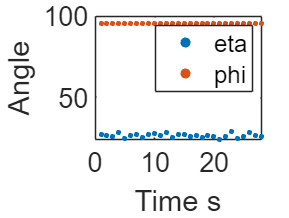


figure;

scatter(1:length(S2),eta,10,'filled')
hold on;
scatter(1:length(S2),phi,10,'filled')
%ylim([-1 1]);
box on;
set(gca,'FontSize',16);
xlabel('Time s');
ylabel('Angle');
legend({'eta','phi'});

mean(S1)

ans = 0.0491

mean(S2)

ans = 0.0662

mean(S3)

ans = -0.9967

% mean(eta)
% mean(phi)
std(S1)

ans = 0.0035

std(S2)

ans = 0.0030

std(S3)

ans = 4.6004e-04

% std(eta)
% std(phi)

disp([num2str(roundn(mean(S1),-4),'%.4f'),'(',num2str(round(std(S1)*10000)),')'])

0.0491(35)


disp([num2str(roundn(mean(S2),-4),'%.4f'),'(',num2str(round(std(S2)*10000)),')'])

0.0662(30)


disp([num2str(roundn(mean(S3),-4),'%.4f'),'(',num2str(round(std(S3)*10000)),')'])

-0.9967(5)
